## Import BIDS dataset

**Run 'eeglab' from the folder containing the eeglab codes. This will add all the relevant EEGLAB functions and directories to path.**

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.8 (see >> help eegplugin_clean_rawdata) - new version 2.7 available
EEGLAB: adding "dipfit" v5.0 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.6 (see >> help eegplugin_firfilt)


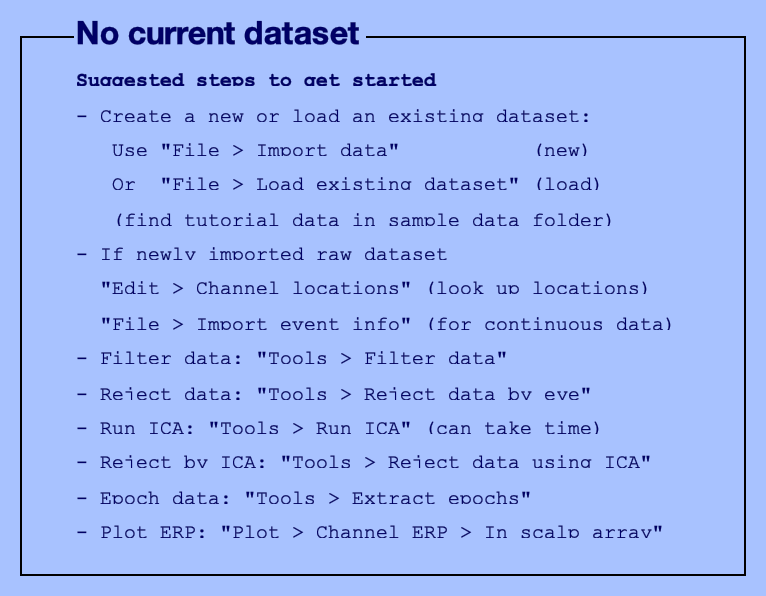

You are using the latest version of EEGLAB.


eeglab

**Steps:**

Select the BIDS folder to work on

BIDS_path = uigetdir(pwd,'Select BIDS dataset folder')

BIDS_path = '/Users/mannaz/Documents/MATLAB/study_ml/ds004186'

Add the folder and subfolders to path. Make the selected BIDS folder to current directory.

addpath(genpath(BIDS_path))

current_path = pwd;
if strcmp(current_path,BIDS_path)==0
    disp('Changing current directory to BIDS dataset folder')
    cd(BIDS_path)
end

Changing current directory to BIDS dataset folder


[~,dataset_name,~] = fileparts(BIDS_path) 

dataset_name = 'ds004186'

The function pop_importbids() imports a BIDS format folder structure into an EEGLAB study. 

If 'bidsevent' is 'on' then events will be imported from the BIDS .tsv event file and events in the raw binary EEG files will be ignored. Similarly 'bidschanloc', 'on' will import channel locations from BIDS .tsv file and ignore any locations in raw EEG files. The 'studyName' field lets you specify the name of the newly created STUDY.

[STUDY, ALLEEG, opt] = pop_importbids(BIDS_path,'bidsevent','on','bidschanloc','off','studyName',dataset_name);

## BIDS_DL plugin

% Delete any pre-exisiting parallel pools
% delete(gcp('nocreate'));

pop_bids_dl(STUDY, ALLEEG,'aws_path','s3://openneuro.org/'); % for ds004186

## Training with image data

## Create the datastore

train_imds = imageDatastore('~/Documents/MATLAB/ml_study/ds004186/mat_files', 'FileExtensions','.mat','IncludeSubfolders',true);

## Custom reader function

%load_sample = @(x) x.Z_12; 
%readfun = @(x) load_sample(load(x));

readfun = @(x) load(x);

train_imds.ReadFcn = readfun;

## Preview the first sample of the datastore

sample = preview(train_imds);
fprintf('Sample size = %d, %d, %d\n', size(sample));

## Assign labels

train_label_info = readtable('ds004186_labels.csv');
train_label_info_sorted = sortrows(train_label_info,1);
label_col =train_label_info_sorted.Var5; % sex of the subject has header Var5 
train_imds.Labels = categorical(label_col);

Note: the labels here have been sorted to match the order of Files (works for Mac/Linux and AWS - need to check for Windows).

## Define the network layers to be trained

channels = [12, 12]; %range of channels 
num_samples = 2048; %num of samples
image_size = [channels(1) channels(2) 2048]; 

num_labels = size(unique(train_imds.Labels),1);

layers = [
    imageInputLayer(image_size,"Name","imageinput","Normalization","none")
    convolution2dLayer([3 3],16,"Name","conv1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_1")
    convolution2dLayer([3 3],16,"Name","conv2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_2")
    maxPooling2dLayer([2 2],"Name","pool1","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],32,"Name","conv3","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_1")
    convolution2dLayer([3 3],32,"Name","conv4","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_2")
    maxPooling2dLayer([2 2],"Name","pool2","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],64,"Name","conv5","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_1")
    convolution2dLayer([3 3],64,"Name","conv6","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_2")
    convolution2dLayer([3 3],64,"Name","conv7","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_3")
    maxPooling2dLayer([2 2],"Name","pool3","Padding","same","Stride",[2 2])
    fullyConnectedLayer(1024,"Name","fc1","WeightL2Factor",0)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop1")
    fullyConnectedLayer(1024,"Name","fc2","WeightL2Factor",0)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop2")
    fullyConnectedLayer(num_labels,"Name","fc3","WeightL2Factor",0)
    softmaxLayer("Name","prob")
    classificationLayer("Name","classoutput")];

## Training the network

Define training settings. There are several [training options](https://in.mathworks.com/help/deeplearning/ref/trainingoptions.html) available. Try different options to improve performance.

options = trainingOptions('adam', ...
    'InitialLearnRate',0.0005, ...
    'SquaredGradientDecayFactor',0.99, ...
    'MaxEpochs',40, ...
    'MiniBatchSize',40);
    

Train the network

eeg_net = trainNetwork(train_imds,layers,options);